%{
ES115 Engineering Computer Applications 
Module 1 Project: Autonomous Cart Speed Profile

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 22, 2026

Purpose:
The purpose of this project is to analyze an autonomous cart's motion using a
 quadratic speed model. By using MATLAB to calculate velocity and estimate 
acceleration, we can identify key performance moments, such as when the cart hits 
its top speed and its acceleration hits zero. This shows how engineering models help
 predict and control vehicle behavior.

Inputs:
- Time Range (t): 0 to 20 seconds
- Step Size: 0.2 seconds
- Speed Equation: (v(t) = -0.2(t - 10)^2 + 20)

Outputs:
- Velocity Vector (v): Speed values calculated at every time step
- Acceleration Vector (a): Numerical derivative representing the rate of speed change
- Max Speed Report: Time and magnitude of the peak velocity
- Visualizations: Speed vs. Time and Acceleration vs. Time plots.

Engineering Workflows:
- Kinematic Modeling: Defining motion through mathematical functions
- Numerical Differentiation: Estimating acceleration using the change in velocity over time (Delta v / Delta t)
- Performance Analysis: Identifying the relationship between peak velocity and zero acceleration.

MATLAB Tools:
- diff(): Calculates numerical differences between adjacent vector elements
- max(): Finds the maximum value and its index in a dataset
- plot(): Generates visual profiles for speed and acceleration
- fprintf(): Displays the final analysis results in the command window.
%}


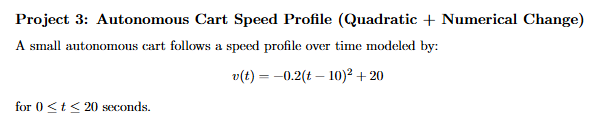

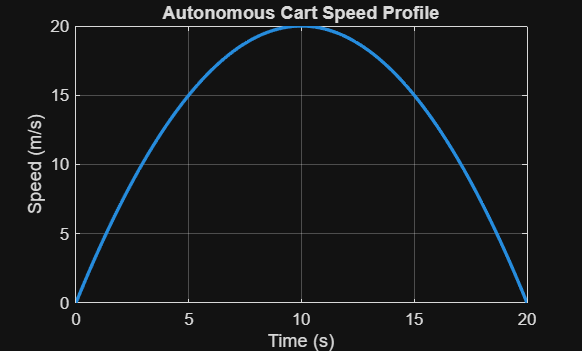

t = 0:0.2:20;
v = -0.2*(t - 10).^2 + 20;

figure;
plot(t, v, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Autonomous Cart Speed Profile');

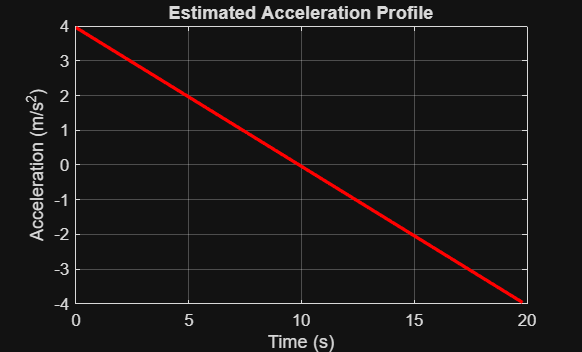


a = diff(v) ./ diff(t);
t_accel = t(1:end-1);

figure;
plot(t_accel, a, 'r', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Estimated Acceleration Profile');


[max_v, idx] = max(v);
t_max = t(idx);
a_near_max = a(max(1, idx-1));

fprintf('Max speed of %.2f m/s occurs at t = %.2f s\n', max_v, t_max);

Max speed of 20.00 m/s occurs at t = 10.00 s


fprintf('Acceleration near max speed is approximately %.2f m/s^2\n', a_near_max);

Acceleration near max speed is approximately 0.04 m/s^2
